% AAE 564 HW 7 MATLAB Code
% Tomoki Koike
clear all; close all; clc;
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');

% % Problem 2
% % Method 1 expm()
% A = [0, 1; 1, 0];
% t = log(2);
% eA1 = expm(A*t);

% Method 2 numerical simulation 
% tspan = 0:0.1:10;
% A = [0, 1; 1, 0];
% x0 = [1, 0];
% res = ode45(@(t,x) numSim(t,x,A), tspan, x0)
% E1 = deval(res, log(2))
% 
% x0 = [0, 1];
% res = ode45(@(t,x) numSim(t,x,A), tspan, x0)
% E2 = deval(res, log(2))


% % Method 3 Jordan 
% [v, d] = eig(A)
% T = [-1, 1; 1, 1];
% Phi = T*[exp(d(1,1)*t), 0; 0, exp(d(2,2)*t)]/T

% % Method 4 Laplace Transform
% a = 0.5*(exp(-t)+exp(t))

% % Problem 3
% syms t
% A = [3, -5; -5, 3];
% [v, d] = eig(A)
% T = [1, 1; 1, -1];
% inv(T)
% eA = expm(A*t)

% [r, p, k] = residue([1,-3],[1,-6,-16])
% [r, p, k] = residue([0,5],[1,-6,-16])

% % Problem 4
% A = [0, 1; -1, 0];
% t = log(2);
% eA = expm(A*t)

% % exercise 55
% A = [-5, 2; -12, 5]
% [v, d] = eig(A)
% syms t
% eA = expm(A*t)
% 
% T = [1, 1; 3, 2]
% eA = simplify(T*expm(-d*t)/T)

% xt = eA * [1;3]

% exercise 6
% A = [-1,0,0,0; 1,-2,0,0; 1,0,-3,0; 1,1,1,1];
% syms lambda t
% ss = A-lambda*eye(4);
% temp = det(ss);
% [v,d] = eig(A)
% ss1 = subs(ss, lambda, d(1,1))
% ss1_rref = rref(ss1)
% ss2 = subs(ss, lambda, d(2,2))
% ss2_rref = rref(ss2)
% ss3 = subs(ss, lambda, d(3,3))
% ss3_rref = rref(ss3)
% ss4 = subs(ss, lambda, d(4,4))
% ss4_rref = rref(ss4)
% eA = expm(A*t)
% temp = eA * [0;0;1;0]

% temp = [0,0,1,0] * eA * [0;0;1;0]

% exercise 7
% syms lambda t
% A = [0, 1; -2, -3];
% ss = A-lambda*eye(2);
% temp = det(ss);

% [v, d] = eig(A)
% eA = expm(A*t)
% 
% ss1 = subs(ss, lambda, d(1,1))
% ss1_rref = rref(ss1)
% ss2 = subs(ss, lambda, d(2,2))
% ss2_rref = rref(ss2)

% % Proof
% syms t s
% eA = expm(A*t)
% trans = C*eA
% lambda = -2;
% G = simplify(C*inv(s*eye(2)-A)*B+D)
% sspart = exp(lambda*t)*G

% % Matrices
% A = [0, 1; -2, -3];
% B = [0; 1];
% C = [3, -1];
% D = 0;
% 
% lambda = 3;
% 
% % random numbers between 0 and 20
% low = -20; high = 20;
% x01 = low + (high - low) * rand(2,1)

x01 =    10.3096
    9.7253


% x02 = low + (high - low) * rand(2,1)

x02 =    -4.3109
    6.2191


% sim('ex7_v2');

% % Matrices
% A = [0, 1; -2, -3];
% B = [0; 1];
% C = [-1, -3];
% D = 1;
% 
% lambda = 1; 
% 
% % random numbers between -20 and 20
% low = -20; high = 20;
% x01 = low + (high - low) * rand(2,1)

x01 =   -13.1525
    8.2418


% x02 = low + (high - low) * rand(2,1)

x02 =   -18.7267
   -8.9231


% sim('ex7_v2');

% Exercise 9

% (a)
% Set parameters and equilibrium conditions
% m = [2,1,1]; l = [1,0.5]; g = 1; % P4
% ye = 0; theta1e = 0; theta2e = 0; % E1
% 
% k = 1;    % spring constant
% c = 1;    % damping coefficient

% xe = trim("db_pend_cart_lin_modInput")

xe =      0
     0
     0
     0
     0
     0


ue = 0

ye =      0
     0
     0


dxe =      0
     0
     0
     0
     0
     0


% [A, B, C, D] = linmod("db_pend_cart_lin_modInput",xe)

A =          0         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0         0
         0         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0         0    1.0000
         0         0         0   -0.5000   -0.5000         0         0         0
         0         0         0   -1.5000   -0.5000         0         0         0
         0         0         0   -1.0000   -3.0000         0         0         0


B =          0
         0
         0
         0
         0
    0.5000
    0.5000
    1.0000


C =      1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0


D =      0
     0
     0
     0
     0


% sys_ss = ss(A, B, C, D);  % get the state space system
% sys_tf = tf(sys_ss)  % get the transfer function 

sys_tf =
 
  From input to output...
   1:  0
 
   2:  0
 
   3:  0
 
   4:  0
 
   5:  0
 
Static gain.



% p = pole(sys_tf)  % get the eigenvalues 


p =

  0×1 empty double column vector



% 
% % Define a transfer function for each one to obtain the zeros
% tf1 = tf(sys_tf.Numerator(1), sys_tf.Denominator(1))

tf1 =
 
  0
 
Static gain.



% tf2 = tf(sys_tf.Numerator(2), sys_tf.Denominator(2))

tf2 =
 
  0
 
Static gain.



% tf3 = tf(sys_tf.Numerator(3), sys_tf.Denominator(3))

tf3 =
 
  0
 
Static gain.



% z1 = zero(tf1)


z1 =

  0×1 empty double column vector



% z2 = zero(tf2)


z2 =

  0×1 empty double column vector



% z3 = zero(tf3)


z3 =

  0×1 empty double column vector



% p1 = pole(tf1)


p1 =

  0×1 empty double column vector



% p2 = pole(tf2)


p2 =

  0×1 empty double column vector



% p3 = pole(tf3)


p3 =

  0×1 empty double column vector



% % Proof
syms t s
G = vpa(simplify(C*inv(s*eye(6)-A)*B+D))

$$G = \begin{array}{l} \left(\begin{array}{c} \frac{1.6226e+32\,s^{4}+4.8678e+32\,s^{2}+3.2452e+32}{\sigma_{1}}\\ \frac{1.8014e+16\,s^{2}\,\left(9.0072e+15\,s^{2}+1.8014e+16\right)}{\sigma_{1}}\\ \frac{1.8014e+16\,s^{2}\,\left(1.8014e+16\,s^{2}+1.8014e+16\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=3.2452e+32\,s^{6}+1.6226e+32\,s^{5}+1.6226e+33\,s^{4}+4.8678e+32\,s^{3}+1.7849e+33\,s^{2}+3.2452e+32\,s+3.2452e+32 \end{array}$$

res1 = solve(G(1)==0, s)

$$res1 = \left(\begin{array}{c} -1.4142\,\mathrm{i}\\ -1.000\,\mathrm{i}\\ 1.000\,\mathrm{i}\\ 1.4142\,\mathrm{i} \end{array}\right)$$

res2 = solve(G(2)==0, s)

$$res2 = \left(\begin{array}{c} 0\\ 0\\ -1.4142\,\mathrm{i}\\ 1.4142\,\mathrm{i} \end{array}\right)$$

res3 = solve(G(3)==0, s)

$$res3 = \left(\begin{array}{c} 0\\ 0\\ -1.000\,\mathrm{i}\\ 1.000\,\mathrm{i} \end{array}\right)$$

% (b)
warning("off")
% Set parameters and equilibrium conditions
m = [2,1,1]; l = [1,0.5]; g = 1; % P4
ye = 0; theta1e = 0; theta2e = 0; % E1

k = 1;    % spring constant
c = 1;    % damping coefficient
a = 1;   % amplitude in disturbance
omega = 1;

xe = trim("db_pend_cart_lin_modInput")

xe =      0
     0
     0
     0
     0
     0


[A, B, C, D] = linmod("db_pend_cart_lin_modInput",xe)

A =          0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000
   -0.5000   -0.5000   -0.5000   -0.5000         0         0
   -0.5000   -1.5000   -0.5000   -0.5000         0         0
   -1.0000   -1.0000   -3.0000   -1.0000         0         0


B =          0
         0
         0
    0.5000
    0.5000
    1.0000


C =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0


D =      0
     0
     0



% % % Proof
% syms t s
% G = vpa(simplify(C*inv(s*eye(6)-A)*B+D))
% res1 = solve(G(1)==0, s)
% res2 = solve(G(2)==0, s)
% res3 = solve(G(3)==0, s)

% Initial conditions for the perturbation variables
del_yi = 0; del_theta1i = 0; del_theta2i = 0;
del_yi_dot = 0; del_theta1i_dot = 0; del_theta2i_dot = 0;

% Initial conditions for the variables
yi = ye + del_yi; 
theta1i = theta1e + del_theta1i; 
theta2i = theta2e + del_theta2i;
yi_dot = del_yi_dot; 
theta1i_dot = del_theta1i_dot; 
theta2i_dot = del_theta2i_dot;

% Linearized system 
IC_lin = [del_yi, del_theta1i, del_theta2i, 0, 0, 0];
lin_res = sim('ss_lin_sys');

% Nonlinear system
nonlin_res = sim('db_pend_cart_nonlin_modInput')

nonlin_res =   Simulink.SimulationOutput:

          theta1_nonlin: [1x1 struct] 
          theta2_nonlin: [1x1 struct] 
                   tout: [8572x1 double] 
               y_nonlin: [1x1 struct] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 



% get values from results 

tspan_lin  = lin_res.tout;
y_lin      = lin_res.lin_del_y.signals.values;
theta1_lin = lin_res.lin_del_theta1.signals.values;
theta2_lin = lin_res.lin_del_theta2.signals.values;

tspan_nonlin  = nonlin_res.tout;
y_nonlin      = nonlin_res.y_nonlin.signals.values;
theta1_nonlin = nonlin_res.theta1_nonlin.signals.values;
theta2_nonlin = nonlin_res.theta2_nonlin.signals.values;

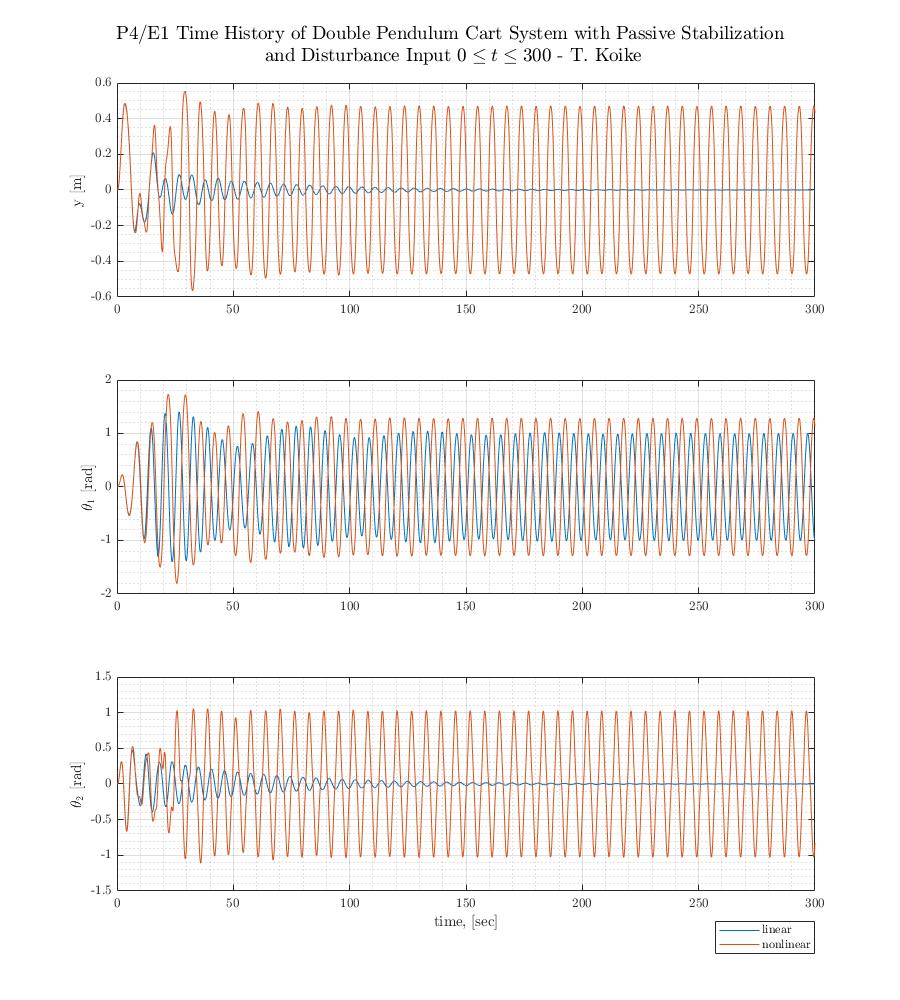


% Plotting 
fig1 = figure('Renderer',"painters", 'Position', [10 10 900 1000]);
subplot(3,1,1)
hold on; grid on; grid minor; box on;
plot(tspan_lin, y_lin)
plot(tspan_nonlin, y_nonlin)
ylabel('y [m]')
hold off
subplot(3,1,2)
hold on; grid on; grid minor; box on;
plot(tspan_lin, theta1_lin)
plot(tspan_nonlin, theta1_nonlin)
ylabel('$\theta_1$ [rad]')
hold off
subplot(3,1,3)
hold on; grid on; grid minor; box on;
plot(tspan_lin, theta2_lin)
plot(tspan_nonlin, theta2_nonlin)
ylabel('$\theta_2$ [rad]')
xlabel('time, [sec]')
h = legend('linear','nonlinear'); set(h, 'Position',  [0.8, 0.05, .1, .025]);
hold off
sgtitle({['P4/E1 Time History of Double Pendulum Cart System with Passive ' ...
    'Stabilization'], ' and Disturbance Input $0\leq t \leq 300$ - T. Koike'})
saveas(fig1, 'p9_b.png')

% function dx = numSim(t, x, A)
%     dx = A*x;
% end